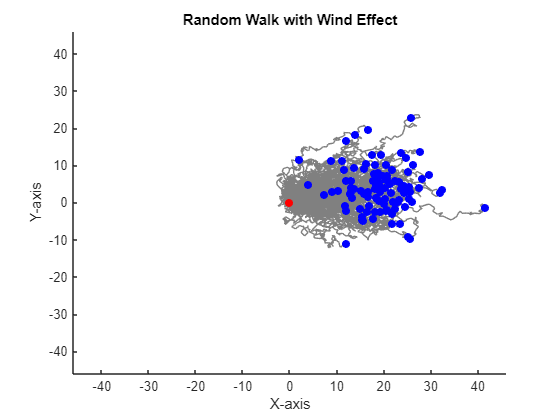

clear 
close

% Input
windStrength = input('Enter wind strength (0 to 10): ');
while windStrength < 0 || windStrength > 10
    windStrength = input('Invalid input. Enter wind strength (0 to 10): ');
end
windDirection = input('Enter wind direction in degrees (0 to 360): ');

% Convert wind direction
wind = deg2rad(windDirection - 90);
wind2 = [cos(wind), sin(wind)] * (windStrength / 10);

% Number of steps and particles
Nstep = 100;
Np = 100;

cMax = 0;
lastPxy = zeros(Np, 2); % Save last coordinates
Z = NaN(Nstep * Np, 1); % All step lengths to calculate average step length "l"

paths = zeros(Nstep, 2, Np);

% Random walk with wind effect
for p = 1:Np
    x = 0;
    y = 0;
    Pxy = zeros(Nstep, 2);
    for i = 1:Nstep 
        dx = 2 * rand - 1 + wind2(1);
        dy = 2 * rand - 1 + wind2(2);
        x = x + dx; % Add step to previous position
        y = y + dy; % Add step to previous position
        Pxy(i, 1) = x;
        Pxy(i, 2) = y;
        Z((i + (p - 1) * Nstep), 1) = sqrt(dx^2 + dy^2);
    end
    paths(:, :, p) = Pxy;
    temp = max(abs(Pxy), [], 'all');
    if temp > cMax
        cMax = temp;
    end
    lastPxy(p, :) = Pxy(Nstep, :);        
end

% Static plot of all paths
figure
hold on
for p = 1:Np
    plot(paths(:, 1, p), paths(:, 2, p), 'Color', [0.5 0.5 0.5]) % Gray color
end

% Plot
scatter(0, 0, 'r', 'filled')
scatter(lastPxy(:, 1), lastPxy(:, 2), 'b', 'filled')
xlim([-cMax * 1.1, cMax * 1.1])
ylim([-cMax * 1.1, cMax * 1.1])
title('Random Walk with Wind Effect')
xlabel('X-axis')
ylabel('Y-axis')



l = mean(Z);
fprintf('sqrt(N)*l is : %8.3f\n', sqrt(Nstep) * l);

sqrt(N)*l is :    7.835


r = mean(sqrt(sum(lastPxy.^2, 2)));
fprintf('r is : %8.4f\n', r);

r is :  20.5487
